# Homework 6

Yuyu Fan

% problem 1
n = 100;
x = [6,52,28,14];
theta0 = 0.4;
theta(1) = theta0;
nth = (theta(1)/(2+theta(1))*x(2)+x(1)+x(4))/(2*(theta(1)/(2+theta(1))*x(2)+x(1)+x(3)+x(4)));
i = 1;
while (abs(theta(i)-nth)>1e-6)
nth = theta(i);
theta(i+1) = (theta(i)/(2+theta(i))*x(2)+x(1)+x(4))/ ...
(2*(theta(i)/(2+theta(i))*x(2)+x(1)+x(3)+x(4)));
i = i+1;
end
theta(end)

ans = 0.2385

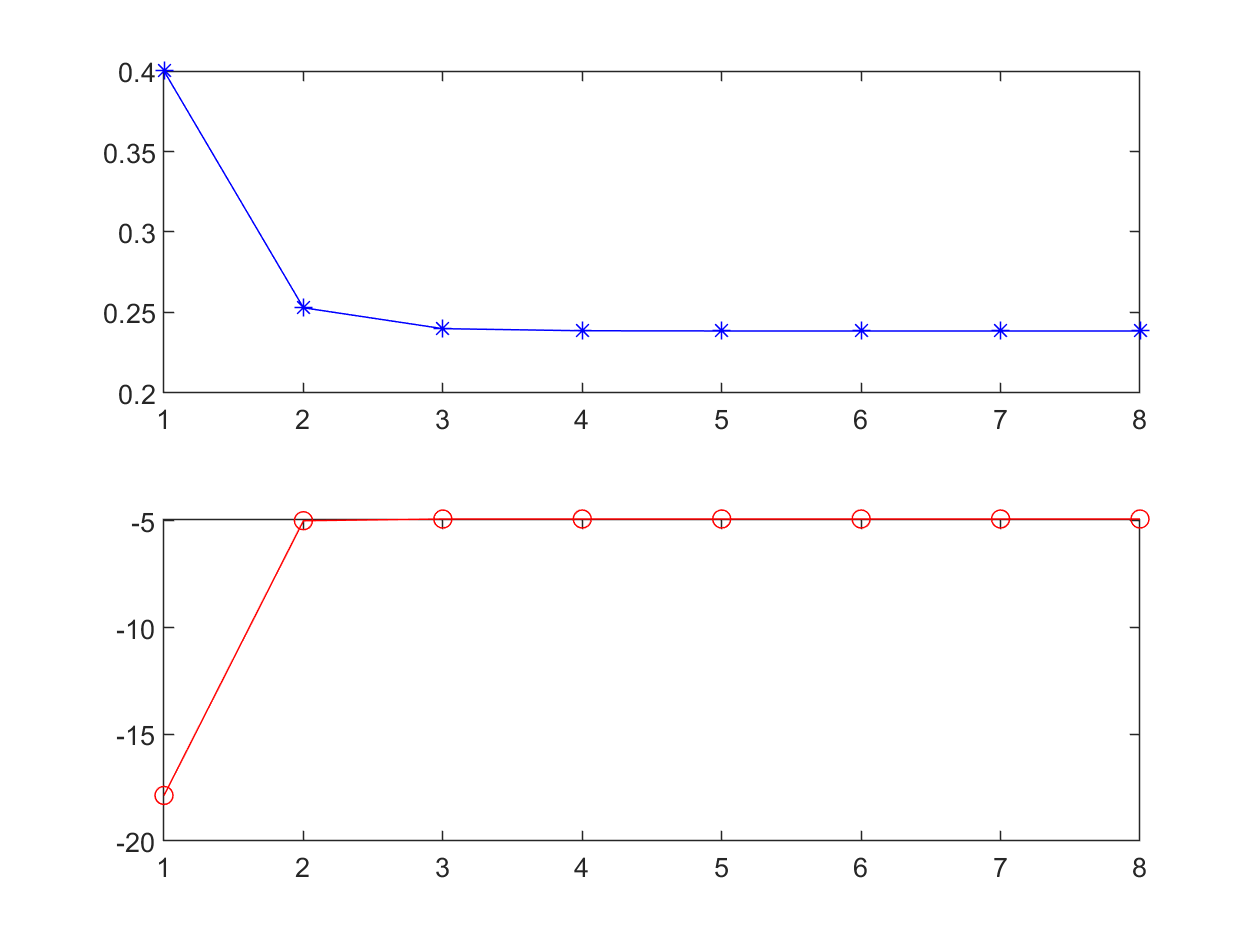

% plot theta 
subplot(211);
plot(theta, 'b-*')

% caculate log-likelihood
K = length(theta);
for k = 1:K
ll(k) = (x(1)+x(4))*log(theta(k)) + x(2)*log(2+theta(k)) + x(3)*log(1-2*theta(k));
end

% plot the log-likelihood
subplot(212);
plot(ll, 'ro-');

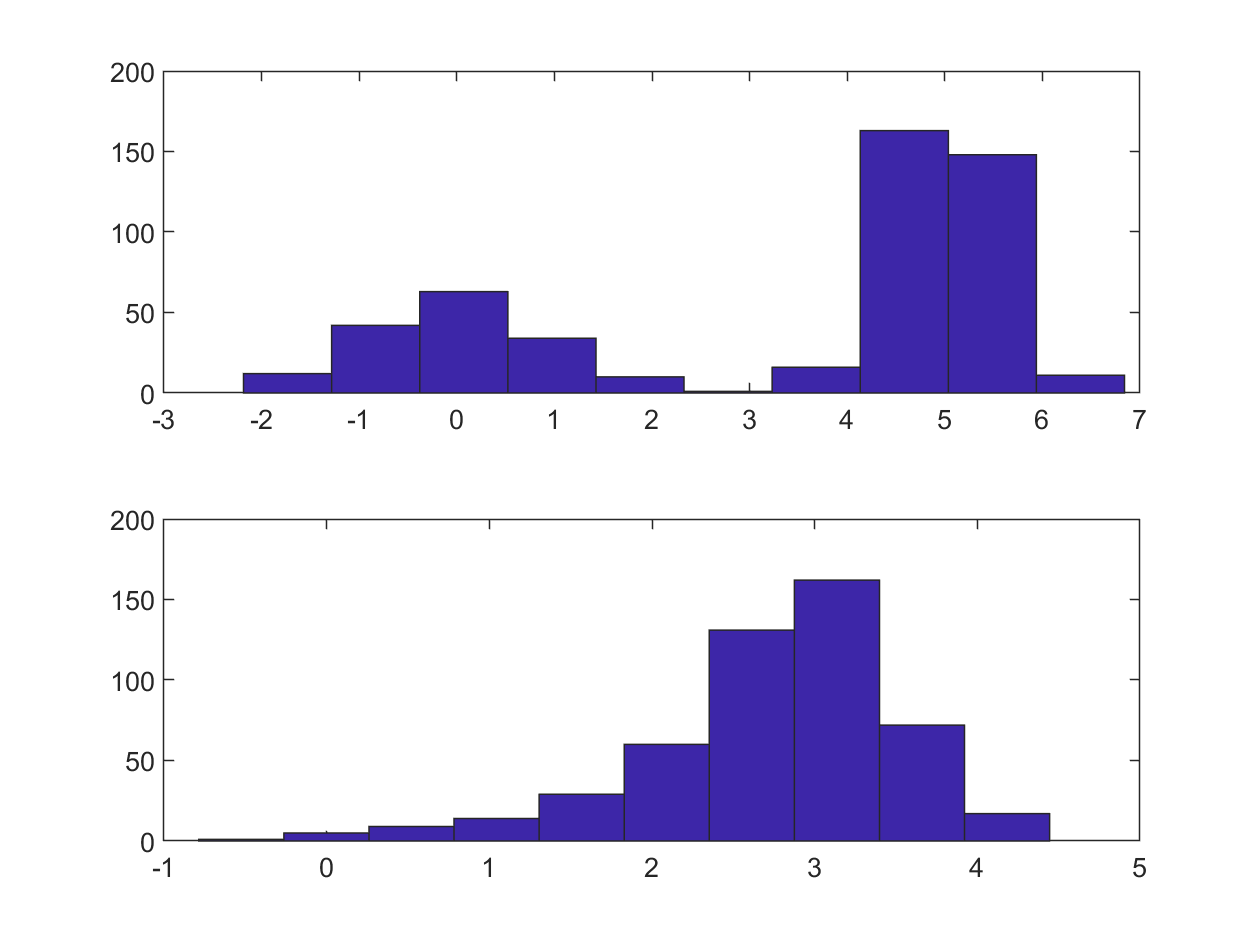

% problem 2

load hw6_2_data1
Y1 = Y;
load hw6_2_data2
Y2 = Y;
figure(1)
subplot(211)
hist(Y1)
subplot(212)
hist(Y2)


type("emnormal.m")


function [alphaest, muest, sigmaest, loglikelihood] = emnormal(Y, alpha, mu, sigma)
n = length(Y);
i = 1;
stop = 1;
loglike(i) = sum(log(alpha(i, 1)*normpdf(Y, mu(i, 1), sigma(i, 1))+...
alpha(i, 2)*normpdf(Y, mu(i, 2), sigma(i, 2))));
while (stop>1e-6)
P(1, :) = alpha(i, 1) * normpdf(Y, mu(i, 1), sigma(i, 1))./...
(alpha(i, 1) * normpdf(Y, mu(i, 1), sigma(i, 1)) + alpha(i, 2)...
* normpdf(Y, mu(i, 2), sigma(i, 2)));
P(2, :) = alpha(i, 2) * normpdf(Y, mu(i, 2), sigma(i, 2))./...
(alpha(i, 1) * normpdf(Y, mu(i, 1), sigma(i, 1)) + alpha(i, 2)...
* normpdf(Y, mu(i, 2), sigma(i, 2)));
alpha(i+1, 1) = 1/n * sum(P(1, :));
alpha(i+1, 2) = 1/n * sum(P(2, :));
mu(i+1, 1) = sum(Y .* P(1, :)) / sum(P(1, :));
mu(i+1, 2) = sum(Y .* P(2, :)) / sum(P(2, :));
sigma(i+1, 1) = sqrt(sum((Y - mu(i+1,1)).^2 .* P(1, :))/sum(P(1, :)));
sigma(i+1, 2) = sqrt(sum((Y - mu(i+1,2)).^2 .* P(2, :))/sum(P(2, :)));
loglike(i+1) = sum(log(alpha(i+1, 1)*normpdf(Y, mu(i+1, 1), sigma(i+1, 1))+...
alpha(i+1, 2)*normpdf(Y,

% for hw6_2_data1
alpha1(1, :) = [0.5 0.5];
mu1(1, :) = [1 4];
sigma1(1, :) = [0.3 0.1];
[alphaest1, muest1, sigmaest1, loglikelihood1] = emnormal(Y1, alpha1, mu1, sigma1);
alphaest1

alphaest1 =     0.3241    0.6759


muest1

muest1 =     0.0269    4.9724


sigmaest1

sigmaest1 =     0.9195    0.5178


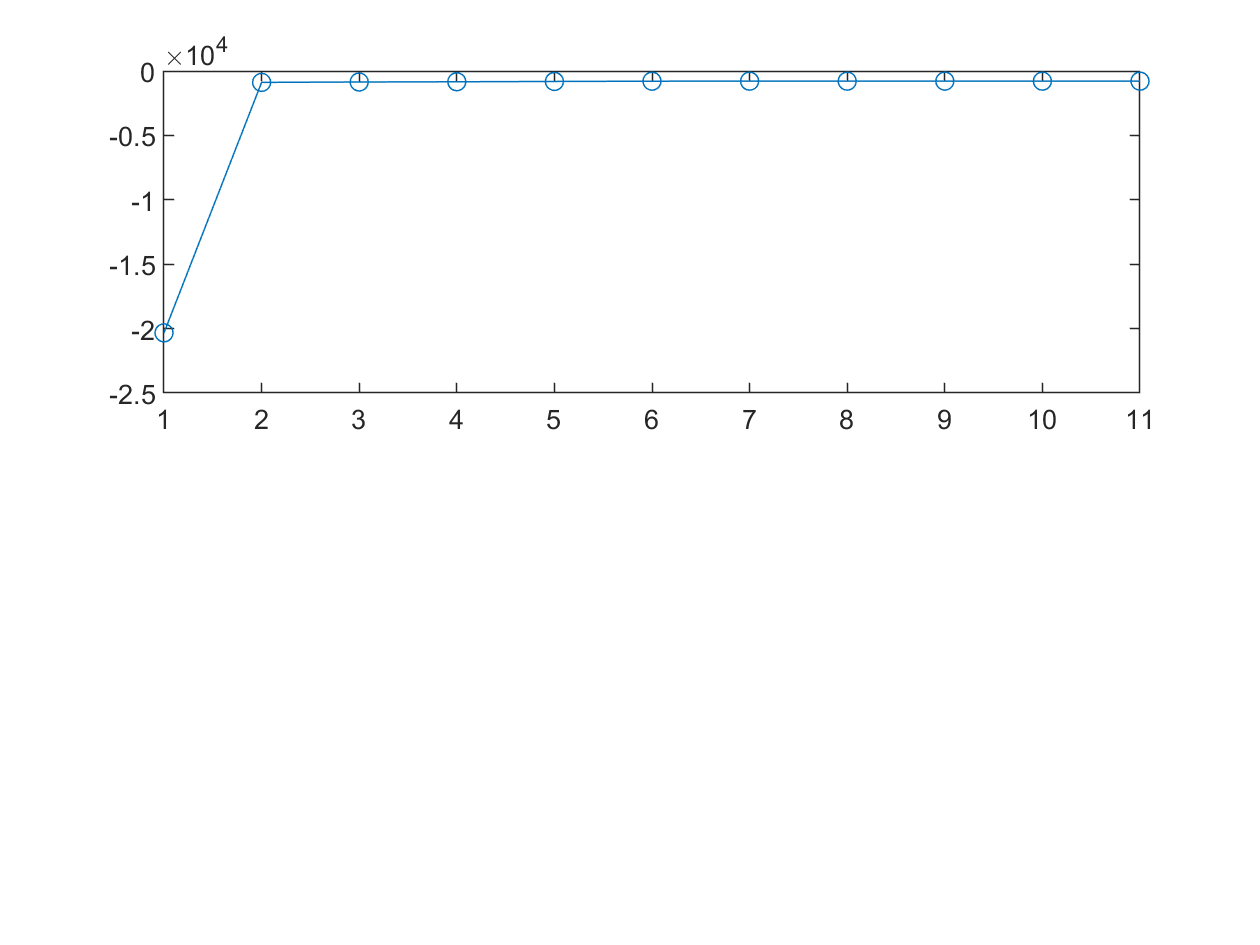

figure(2)
subplot(211)
plot(loglikelihood1,'-o')

% for hw6_2_data2
alpha2(1, :) = [0.5 0.5];
mu2(1, :) = [1 4];
sigma2(1, :) = [0.3 0.1];
[alphaest2, muest2, sigmaest2, loglikelihood2] = emnormal(Y2, alpha2, mu2, sigma2);
alphaest2

alphaest2 =     0.2258    0.7742


muest2

muest2 =     1.8609    3.0171


sigmaest2

sigmaest2 =     0.9298    0.5061


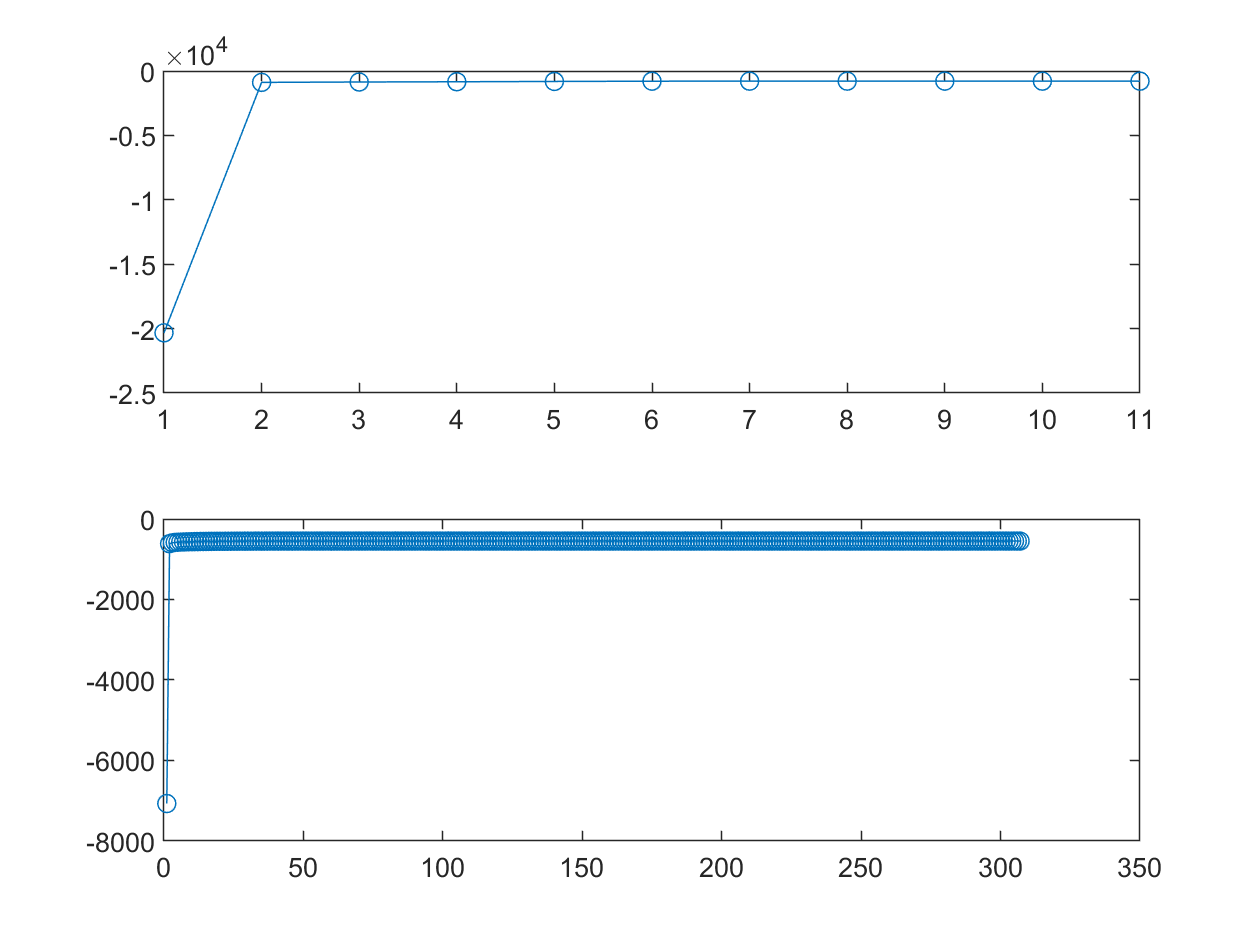

subplot(212)
plot(loglikelihood2,'-o')